save_dir = 'E:\work_Code\Matlab\ZYS\DIY_App\SEEG_Mapper\Atlas\HCPex\surfer_zys\';

surf_file = 'E:\work_Code\Matlab\ZYS\DIY_App\SEEG_Mapper\Atlas\mni152_FSL\surf\rh.white';
[VinnR_raw,F] = read_surf(surf_file); V = VinnR_raw;
surf_file = 'E:\work_Code\Matlab\ZYS\DIY_App\SEEG_Mapper\Atlas\mni152_FSL\surf\rh.pial';
[VoutR_raw,F] = read_surf(surf_file); VmidR_raw = (VinnR_raw+VoutR_raw)/2;

VinnR_raw = VinnR_raw + mni_gray.shape/2;
VmidR_raw = VmidR_raw + mni_gray.shape/2;
VoutR_raw = VoutR_raw + mni_gray.shape/2;

V = V + mni_gray.shape/2;
size(V,1)

ans =       157000


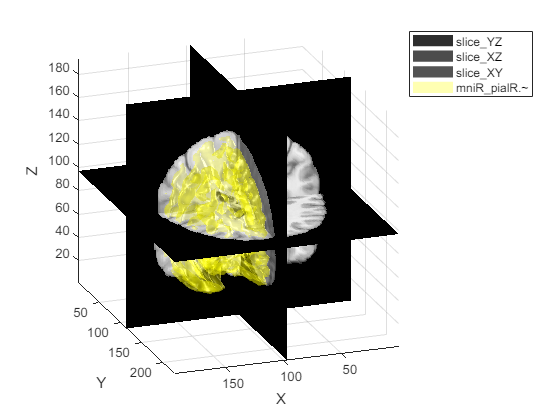

sMRI [229,193,193] res:[1,1,1]


F = F+1;

% surf_file = 'D:\File\work_file\Dataset\Brain\openFCD\sub-00004\surf\T1_reg.DL.right.inner.ply';
% surf_ply = Surf_read_Data(surf_file); V = surf_ply.Vertices; F = surf_ply.Faces;
% 
mniR_pialR = struct('Vertices',V,'Faces',F);

figure; colormap gray
next; slice_mri(mni_gray); hold on; plot_surf(mniR_pialR,'colors',[1,1,0],'alphas',0.3); view(160,20)

tic
temp = mniR_pialR;
temp = Surf_func_ROI(mniR_pialR,'reduce',2); % 2
mniR_pialR_bin2 = Surf_remesh(temp,'len',1.8); % 1.8
size(mniR_pialR_bin2.Vertices,1)

ans =        42783


size(mniR_pialR_bin2.Vertices,1)*2 - size(mniR_pialR_bin2.Faces,1)

ans =      4


toc

历时 14.035289 秒。


# white annoation

% [vertices, label, colortable] = read_annotation('E:\work_Code\Matlab\ZYS\DIY_App\SEEG_Mapper\Atlas\mni152_FSL\label\rh.aparc.annot');
% [label_uniq,~,label_re] = unique(label);
% cmap_raw = colortable.table;
% [~,idxR] = ismember(cmap_raw(:,5),label_uniq);
% idxR(idxR==0) = [];
% cmap_re = cmap_raw(idxR,1:3);
% vidxR_iswhite = label_re==1 & mniR_pialR.Vertices(:,1)<101 & mniR_pialR.Vertices(:,3)>75;
% 
% figure;
% next; plot_surf(mniR_pialR,'colors',label_re); next; plot_surf(mniR_pialR,'colors',double(vidxR_iswhite))
% lay_fig([12,3]); lay_fig('func','legend off; axis off'); lay_linkview(gcf,'view'); view(-90,0); colormap(cmap_re/250)

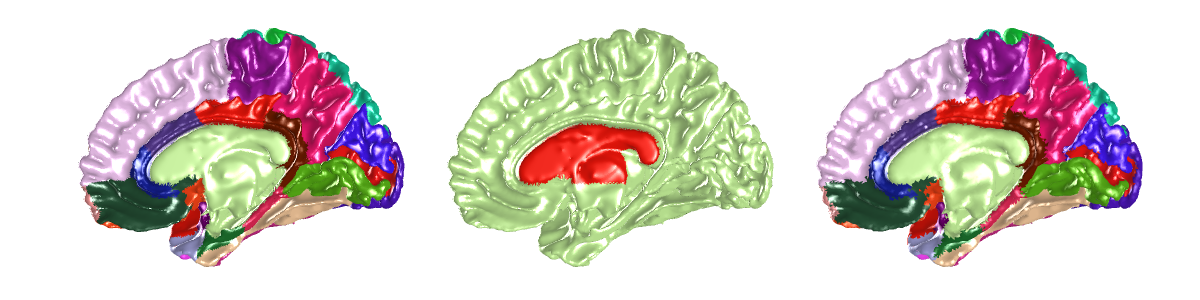

[vertices, label, colortable] = read_annotation('E:\work_Code\Matlab\ZYS\DIY_App\SEEG_Mapper\Atlas\mni152_FSL\label\rh.aparc.annot');
[label_uniq,~,label_re] = unique(label);
cmap_raw = colortable.table;
[~,idxR] = ismember(cmap_raw(:,5),label_uniq);
idxR(idxR==0) = [];
cmap_FSLre = cmap_raw(idxR,1:3)/255;

vidxR_iswhite = label_re==1 & mniR_pialR.Vertices(:,1)<101 & mniR_pialR.Vertices(:,3)>75;

[vidxR_match] = knnsearch(mniR_pialR.Vertices,mniR_pialR_bin2.Vertices);
mniR_pialR_bin2.Labels_FSL = label_re(vidxR_match);
mniR_pialR_bin2.cmap_FSLre = cmap_FSLre;
mniR_pialR_bin2.vidxL_match = vidxR_match;

figure; lay_sub(1,3)
next; plot_surf(mniR_pialR,'colors',label_re); next; plot_surf(mniR_pialR,'colors',double(vidxR_iswhite))
next; plot_surf(mniR_pialR_bin2,'colors',mniR_pialR_bin2.Labels_FSL);
lay_fig([12,3]); lay_fig('func','legend off; axis off'); lay_linkview(gcf,'view'); view(-90,0); colormap(cmap_FSLre)

# BST label

mniR_pialR_bin2.VinnR = VinnR_raw(vidxR_match,:);
mniR_pialR_bin2.VmidR = VmidR_raw(vidxR_match,:);
mniR_pialR_bin2.VoutR = VoutR_raw(vidxR_match,:);
mniR_pialR_bin2.Labels_BST = MRI_func_ROI(mni_atlas,'sample','pos',mniR_pialR_bin2.VmidR,'method',0);

Surf_save_File(mniR_pialR_bin2,[save_dir,'mniR_pialR_bin2.~']);

    1: E:\work_Code\Matlab\ZYS\DIY_App\SEEG_Mapper\Atlas\HCPex\surfer_zys\mniR_pialR_bin2.~    



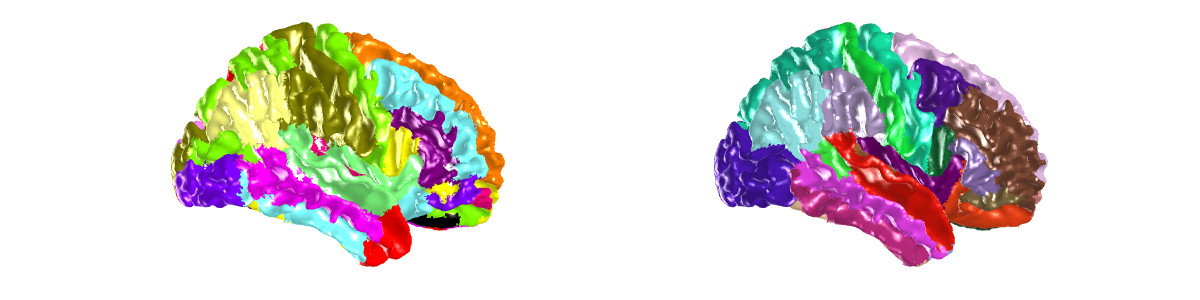


figure;
next; colormapa(atlas_cmap); plot_surf(mniR_pialR_bin2,'colors',mniR_pialR_bin2.Labels_BST); caxis([0 size(atlas_cmap,1)])
next; colormapa(cmap_FSLre); plot_surf(mniR_pialR_bin2,'colors',mniR_pialR_bin2.Labels_FSL);
lay_fig([12,3]); lay_fig('func','legend off; axis off'); lay_linkview(gcf,'view'); view(90,0)

# surface 3D registration

tic
[mniR_sm3_rd, idxR_rd1] = Surf_func_ROI(mniR_sm3,'reduce','bin',8,'get_idx',1);
[subjR_sm3_rd, idxR_rd2] = Surf_func_ROI(subjR_sm3,'reduce','bin',8,'get_idx',1);

[surf_reg_rd,rotVecs] = Surf_warp(subjR_sm3_rd,mniR_sm3_rd,'pointcloud_reg_icp','pc_para',{'Metric','pointToPlane'}); % must use pointToPlane !
[surf_reg_rd] = Surf_warp(surf_reg_rd,mniR_sm3_rd,'pointcloud_reg_cpd','norm_init',0, ...
         'param',{'MaxIterations',30,'OutlierRatio',0.1,'InteractionSigma',0.1,'SmoothingWeight',0.1}); % 1e-4 for fast, 4s
toc

历时 41.316645 秒。


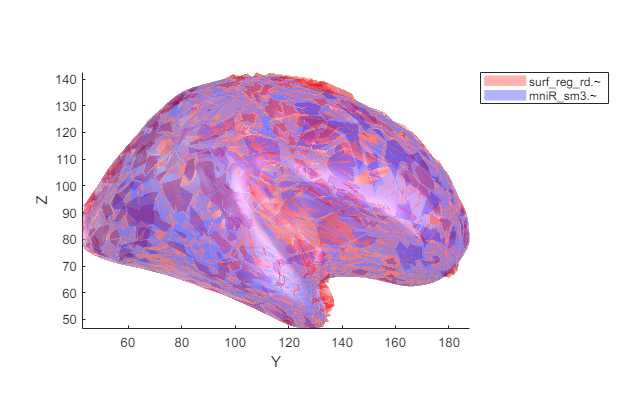


figure;
next; plot_surf(surf_reg_rd,'colors',[1,0,0],'alphas',0.3)
hold on; plot_surf(mniR_sm3,'colors',[0,0,1],'alphas',0.3)
view(90,0)

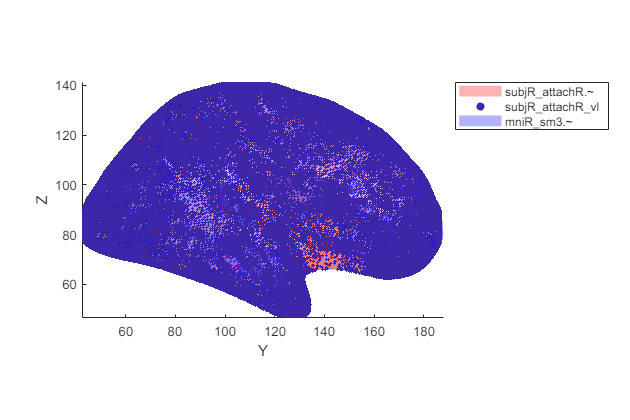

surf_reg = subjR_sm3;
surf_reg.Vertices = interp_sph(subjR_sph.Vertices(idxR_rd2,:),surf_reg_rd.Vertices,subjR_sph.Vertices);
subjR_attachR = surf_reg;

for i = 1:5
    [subjR_attachR] = Surf_smooth(subjR_attachR,'iter',10,'type',3);
    subjR_attachR.Vertices = Surf_func_ROI(mniR_sm3,'attach','pos',subjR_attachR.Vertices);
end
[subjR_attachR] = Surf_smooth(subjR_attachR,'iter',3,'type',3);

figure;
next; plot_surf(subjR_attachR,'colors',[1,0,0],'alphas',0.3,'show_vl',1)
hold on; plot_surf(mniR_sm3,'colors',[0,0,1],'alphas',0.3)
view(90,0)

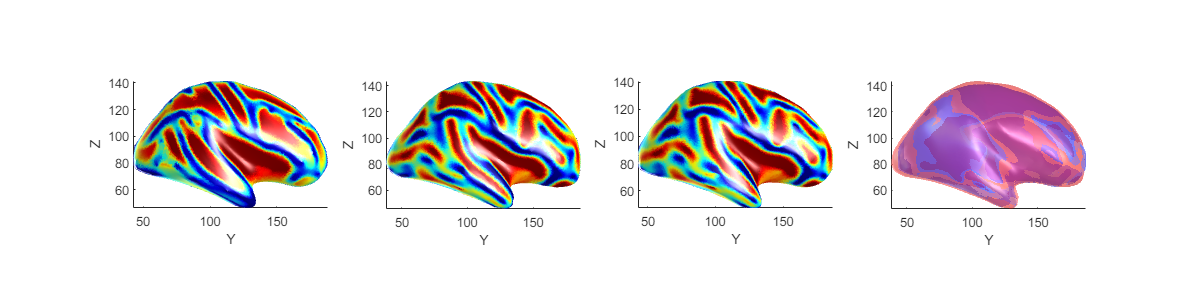

figure; colormap jet
next; plot_surf(mniR_sm3,'colors',mniRK3);
next; plot_surf(subjR_sm3,'colors',subjRK3);
next; plot_surf(subjR_attachR,'colors',subjRK3);
next; plot_surf(subjR_sm3,'colors',[1,0,0],'alphas',0.3); hold on; plot_surf(subjR_attachR,'colors',[0,0,1],'alphas',0.3)
lay_fig([12,3]); lay_fig('func','legend off'); lay_linkview(gcf,'view'); view(90,0)

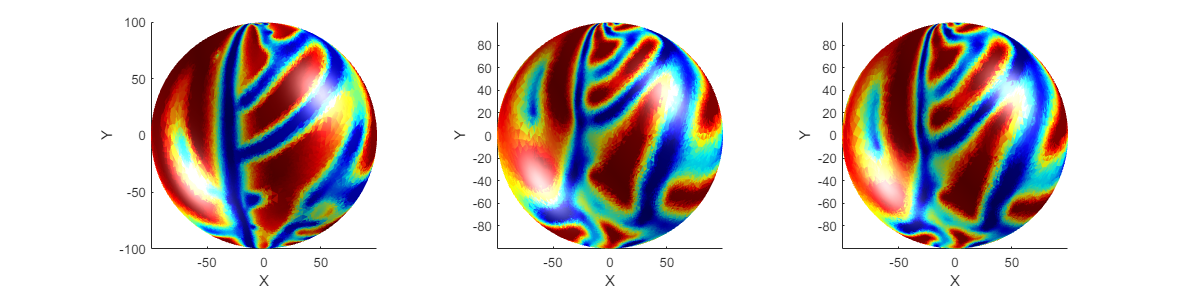

Vat = subjR_attachR.Vertices; VmniR = mniR_sm3.Vertices;
idxR_mniR2subjR = knnsearch(Vat,VmniR);
idxR_subjR2mniR = knnsearch(VmniR,Vat);

subjR_sphreg = subjR_sph; subjR_sphreg.Vertices = mniR_sph.Vertices(idxR_subjR2mniR,:);
[subjR_sphreg] = Surf_smooth(subjR_sphreg,'iter',3,'type',3);
subjR_sphreg.Vertices = subjR_sphreg.Vertices./vecnorm(subjR_sphreg.Vertices,2,2)*SD_atlas.radius;

figure; colormap jet
next; plot_surf(mniR_sph,'colors',mniRK3);
next; plot_surf(subjR_sph,'colors',subjRK3);
next; plot_surf(subjR_sphreg,'colors',subjRK3);
lay_fig([12,3]); lay_fig('func','legend off'); lay_linkview(gcf,'view');

save([save_dir,'subjR_sphreg.mat'],'subjR_attachR','mniR_sm3','idxR_mniR2subjR','idxR_subjR2mniR','subjR_sphreg','subjR_file','subjR_sm3','sm_iters')

Reading from version 2
colortable with 36 entries read (originally /autofs/space/tanha_002/users/greve/fsdev.build/average/colortable_desikan_killiany.txt)


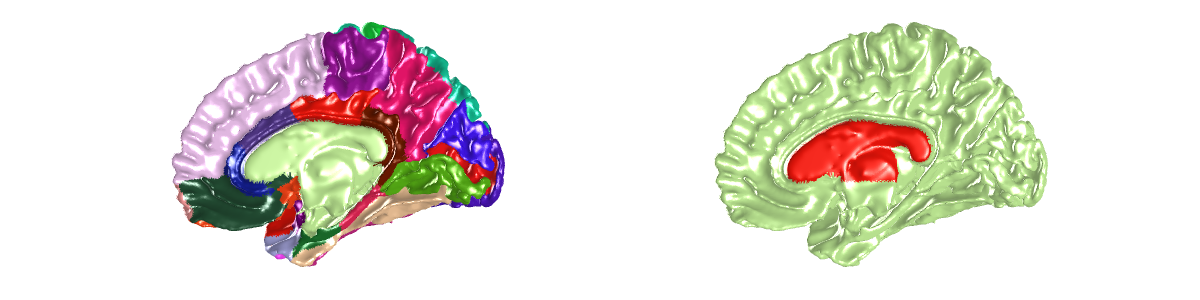

surf_in = mniR_pialR_bin2;

temp = knnsearch(surf_in.Vertices,mniR_pialR.Vertices(vidxR_iswhite,:));
vbinidxR_iswhite = zeros(size(surf_in.Vertices,1),1); vbinidxR_iswhite(temp) = 1;

surf_in.Labels = vbinidxR_iswhite;
tic
for i = 1:2
    evalc("surf_in = Surf_func_filt(surf_in,'V',@median);");
    surf_in.Labels = round(surf_in.Labels);
end
toc

历时 5.495339 秒。


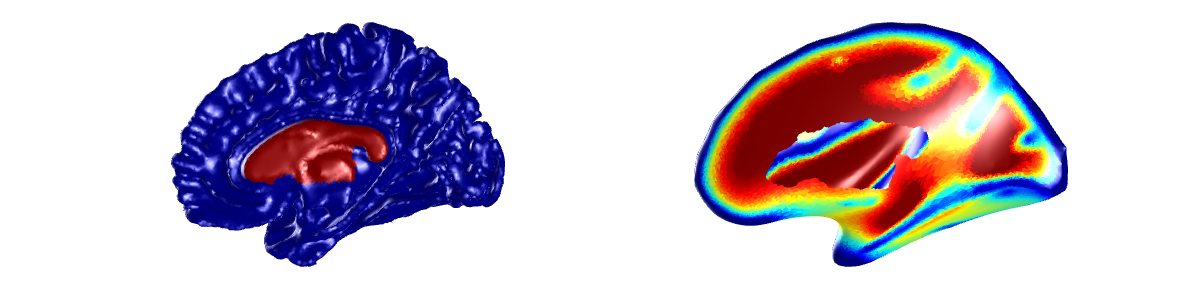

vbinidxR_iswhite = surf_in.Labels;

surf_in = mniR_sm3;
[surf_mniRdiv,~,idxR] = Surf_func_ROI(surf_in,'divide',vbinidxR_iswhite==0);
val = mniRK3(idxR{2});

figure;
next; plot_surf(mniR_pialR_bin2,'colors',vbinidxR_iswhite)
next; plot_surf(surf_mniRdiv{2},'colors',val);
lay_fig([12,3]); lay_fig('func','legend off; axis off'); lay_linkview(gcf,'view'); view(-90,0); colormap jet

temp = Surf_func_ROI(mniR_sm3,'divide',vbinidxR_iswhite>0);
surf_white = Surf_func_ROI(temp{2},'refine',2);
temp = knnsearch(subjR_attachR.Vertices,surf_white.Vertices);
vregidxR_iswhite = zeros(size(subjR_attachR.Vertices,1),1); vregidxR_iswhite(temp) = 1;

surf_in = subjR_attachR;
v = surf_in.Vertices;
% vregidxR_iswhite(v(:,2)<105 & v(:,3)<90) = 0;
surf_in.Labels = vregidxR_iswhite;
tic
for i = 1:1
    evalc("surf_in = Surf_func_filt(surf_in,'V',@median);");
    surf_in.Labels = round(surf_in.Labels);
end
toc

历时 2.228537 秒。


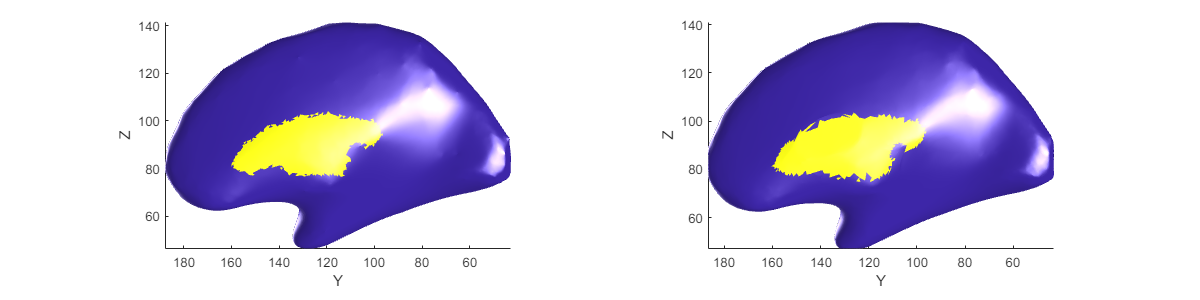

vregidxR_iswhite = surf_in.Labels;

figure;
next; plot_surf(mniR_sm3,'colors',vbinidxR_iswhite)
next; plot_surf(subjR_attachR,'colors',vregidxR_iswhite)
lay_fig([12,3]); lay_fig('func','legend off'); lay_linkview(gcf,'view'); view(-90,0)

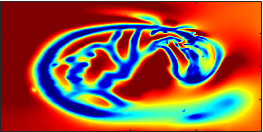

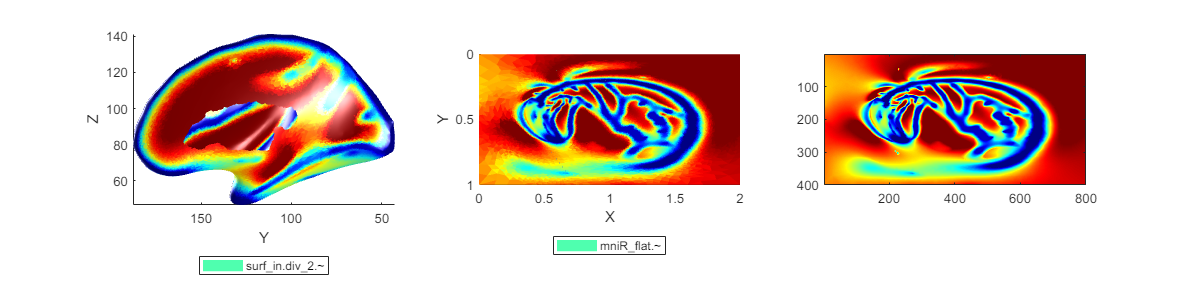

surf_in = mniR_sm3;
square_ratio = 2;
mniR_square_corners = 55;
area_eps = 1e-5;

[surf_mniRdiv,~,idxR] = Surf_func_ROI(surf_in,'divide',vbinidxR_iswhite==0);
vmniR_idxR = idxR{2};
V = mniR_sph.Vertices(vmniR_idxR,:);
F = surf_mniRdiv{2}.Faces;
sph_mniRdiv = struct('Vertices',V,'Faces',F);
[mniR_flat,map_mniR] = Surf_func_GEO(sph_mniRdiv,'mapping_square','corners',mniR_square_corners,'area_eps',area_eps);
map_mniR_max = max(map_mniR,[],1); map_mniR_max(2) = 1;
map_mniR(:,1) = map_mniR(:,1)*square_ratio/map_mniR_max(1); map_mniR_max(1) = square_ratio;
mniR_flat.Vertices(:,[1,2]) = map_mniR;
mniRK3_div = mniRK3(vmniR_idxR); val = mniRK3_div;

texNy = 400;
texNx = round(texNy.*map_mniR_max(1));
func_interp_mniR = @(val) scatteredInterpolant_img(map_mniR,val,map_mniR_max([2,1]),[texNy,texNx]);
img_mniR_raw = func_interp_mniR(val); img_mniR = amp(img_mniR_raw);
imgX_mniR = func_interp_mniR(V(:,1)); imgY_mniR = func_interp_mniR(V(:,2)); imgZ_mniR = func_interp_mniR(V(:,3));
imgXYZ_mniR = cat(3,imgX_mniR,imgY_mniR,imgZ_mniR);

figure;
next; plot_surf(surf_mniRdiv{2},'colors',val); view(-90,0)
next; plot_surf(mniR_flat,'colors',val); lighting none; colormap jet; axis ij;
next; showc(img_mniR)
lay_fig([12,3])

save([save_dir,'mniR_pialR_bin2_flat.mat'],'mniR_sph','vbinidxR_iswhite','vmniR_idxR','sph_mniRdiv', ...
    'mniR_square_corners','mniR_flat','img_mniR_raw','imgXYZ_mniR','mniRK1','mniRK2','mniRK3')

subjR_square_corners = 15;

v = surf_subjR.Vertices;
% v_idxR = (v(:,1)>93 & v(:,2)>80 & v(:,3)>58)>0;

surf_in = subjR_attachR;
[surf_div,~,idxR] = Surf_func_ROI(surf_in,'divide',vregidxR_iswhite==0); surf_div = surf_div{2};
vsubjR_idxR = idxR{2};

V = subjR_sphreg.Vertices(vsubjR_idxR,:); % !!!!! sphreg with sm
F = surf_div.Faces;
sph_subjRdiv = struct('Vertices',V,'Faces',F);

[subjR_flat,map_subjR] = Surf_func_GEO(sph_subjRdiv,'mapping_square','corners',subjR_square_corners,'area_eps',area_eps*2);
map_subjR(:,1) = square_ratio*map_subjR(:,1)/max(map_subjR(:,1));

map_subjR = interp_sph(sph_mniRdiv.Vertices,map_mniR,sph_subjRdiv.Vertices);

subjR_flat.Vertices(:,[1,2]) = map_subjR;
subjRK3_div = subjRK3(vsubjR_idxR); val = subjRK3_div;

img_subjR_raw = scatteredInterpolant_img(map_subjR,val,map_mniR_max([2,1]),[texNy,texNx]);

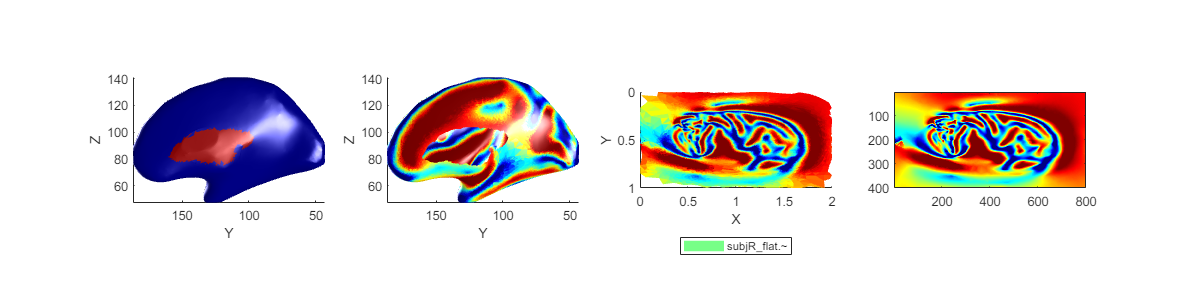

img_subjR = amp(img_subjR_raw);

figure; colormap jet
next; plot_surf(surf_in,'colors',double(vregidxR_iswhite));
next; plot_surf(surf_div,'colors',val); 
% next; plot_surf(subjR_sphreg,'colors',subjRK3);
lay_fig([12,3]); lay_fig('func','legend off'); lay_linkview(gcf,'view'); view(-90,0)
next; plot_surf(subjR_flat,'colors',val); lighting none; axis ij
next; showc(img_subjR)

save([save_dir,'mniR_pialR_bin2.mat'],'mniR_pialR_bin2','vidxR_iswhite','vbinidxR_iswhite','mniR_sm3','mniR_sph')

save([save_dir,'mniR_pialR_bin2_subjRreg.mat'],'subjR_sphreg','vsubjR_idxR','sph_subjRdiv','subjR_flat','subjR_file', ...
    'vregidxR_iswhite','img_subjR_raw','img_mniR_raw')

# use

load([save_dir,'mniR_pialR_bin2_flat.mat'])
load([save_dir,'mniR_pialR_bin2.mat'])
load([save_dir,'mniR_pialR_bin2_subjRreg.mat'])

square_ratio = 2;
mniR_square_corners = 55;
area_eps = 1e-5;
[mniR_flat,map_mniR] = Surf_func_GEO(sph_mniRdiv,'mapping_square','corners',mniR_square_corners,'area_eps',area_eps);

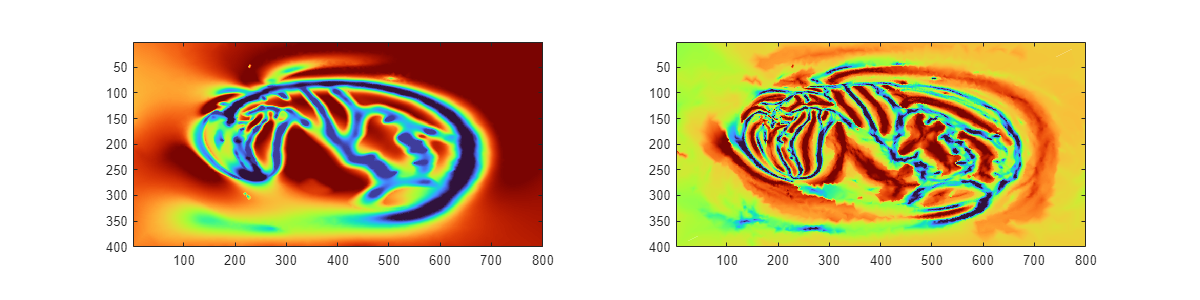

map_mniR_max = max(map_mniR,[],1); map_mniR_max(2) = 1;
texNy = 400;
texNx = 800; %round(texNy.*map_mniR_max(1));

func_interp_mniR = @(val) scatteredInterpolant_img(map_mniR,val,map_mniR_max([2,1]),[texNy,texNx]);

mniRK3_div = mniRK3(vmniR_idxR); val = mniRK3_div;
img_mniR_K3 = func_interp_mniR(val); 

mniRK1_div = mniRK1(vmniR_idxR); val = mniRK1_div;
img_mniR_K1 = func_interp_mniR(val);

figure; colormap turbo
next; showc(img_mniR_K3); next; showc(img_mniR_K1)
lay_fig([12,3])

save([save_dir,'mniR_pialR_bin2_subjRreg.mat'],'subjR_sphreg','vsubjR_idxR','sph_subjRdiv','subjR_flat','subjR_file', ...
    'vregidxR_iswhite','img_subjR_raw','img_mniR_raw','img_mniR_K1','img_mniR_K3')

function val_new = interp_sph(v,val_raw,v_q)
[TH,PHI] = cart2sph(v(:,1),v(:,2),v(:,3));
[TH_q,PHI_q] = cart2sph(v_q(:,1),v_q(:,2),v_q(:,3));

val_new = [];
for i = 1:2
    rot_TH = pi*(i-1);
    th = mod(TH+rot_TH,2*pi);
    th_q = mod(TH_q+rot_TH,2*pi);

    vv_in = [th,PHI];
    vv_q = [th_q,PHI_q];

    for j = 1:size(val_raw,2)
        interp_h = scatteredInterpolant(vv_in,val_raw(:,j));
        val_new(:,j,i) = interp_h(vv_q);
    end
end
w = 1 - abs(mod(TH_q,2*pi)/pi - 1);
w = permute(w,[1,3,2]);
val_new = val_new(:,:,1).*w + val_new(:,:,2).*(1-w);
end

function img = scatteredInterpolant_img(v,val,lim_max,img_sz)
x = linspace(0,lim_max(2),img_sz(2)); y = linspace(0,lim_max(1),img_sz(1));
[X,Y] = meshgrid(x,y);
interp_fmniR = scatteredInterpolant(v,val);
img = interp_fmniR([X(:),Y(:)]);
img = reshape(img,img_sz);
end